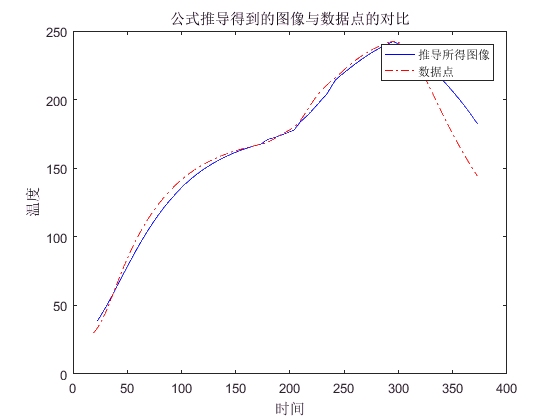

clear
clc
close all
u=70*1e-2/60;
l=0.2;
X=0.15*1e-3/2;
Ftime=hF(u);
a=load('data2.txt');
load('CH.mat')
toT=[175 195 235 255 25];
count=2;
count2=1;
[Ans,index]= hF(u);
Ftime=Ans;
t=Ftime;
T0=34.9+273;

while(1)
    if(count==index(count2,2))
        count2=count2+1;
    end
    
    
    if(count2==5)
        tmp_k(count)=Tk5_Plus_5(T0-273);
    else
        tmp_k(count)=cfK(T0-273,1);%迭代变化量
    end
    
    
    T1=toT(count2)+273;
    t0=t(count-1);
    hc(count)=funairhc_simple(T0-273,u,l);%迭代变化量,T0-273是因为输入的是摄氏度
    
    if(count2~=5)
    T=fun_ti_plus(t(count),t0,T1,T0,hc(count),tmp_k(count),X);
    else
    T=fun_ti_plus_2(t(count),t0,T1,T0,hc(count),tmp_k(count),X);
    end
    
    trT=T-T0;%T0的增量
    T0=T0+trT;%刷新T0

    
    count=count+1;
    
    TJ(count)=T;
      
    if(count==index(end,2))
        break;
    end
    

    
end
TJ(1)=34.9+273;%补充初值
T;
TJ;
newTJ=TJ-273+CH;%修正
plot(t(3:end),newTJ(3:end),'-b')%第二个点离群
hold on
plot(a(:,1),a(:,2),'-.r')
title('公式推导得到的图像与数据点的对比')
xlabel('时间')
ylabel('温度')
legend('推导所得图像','数据点')